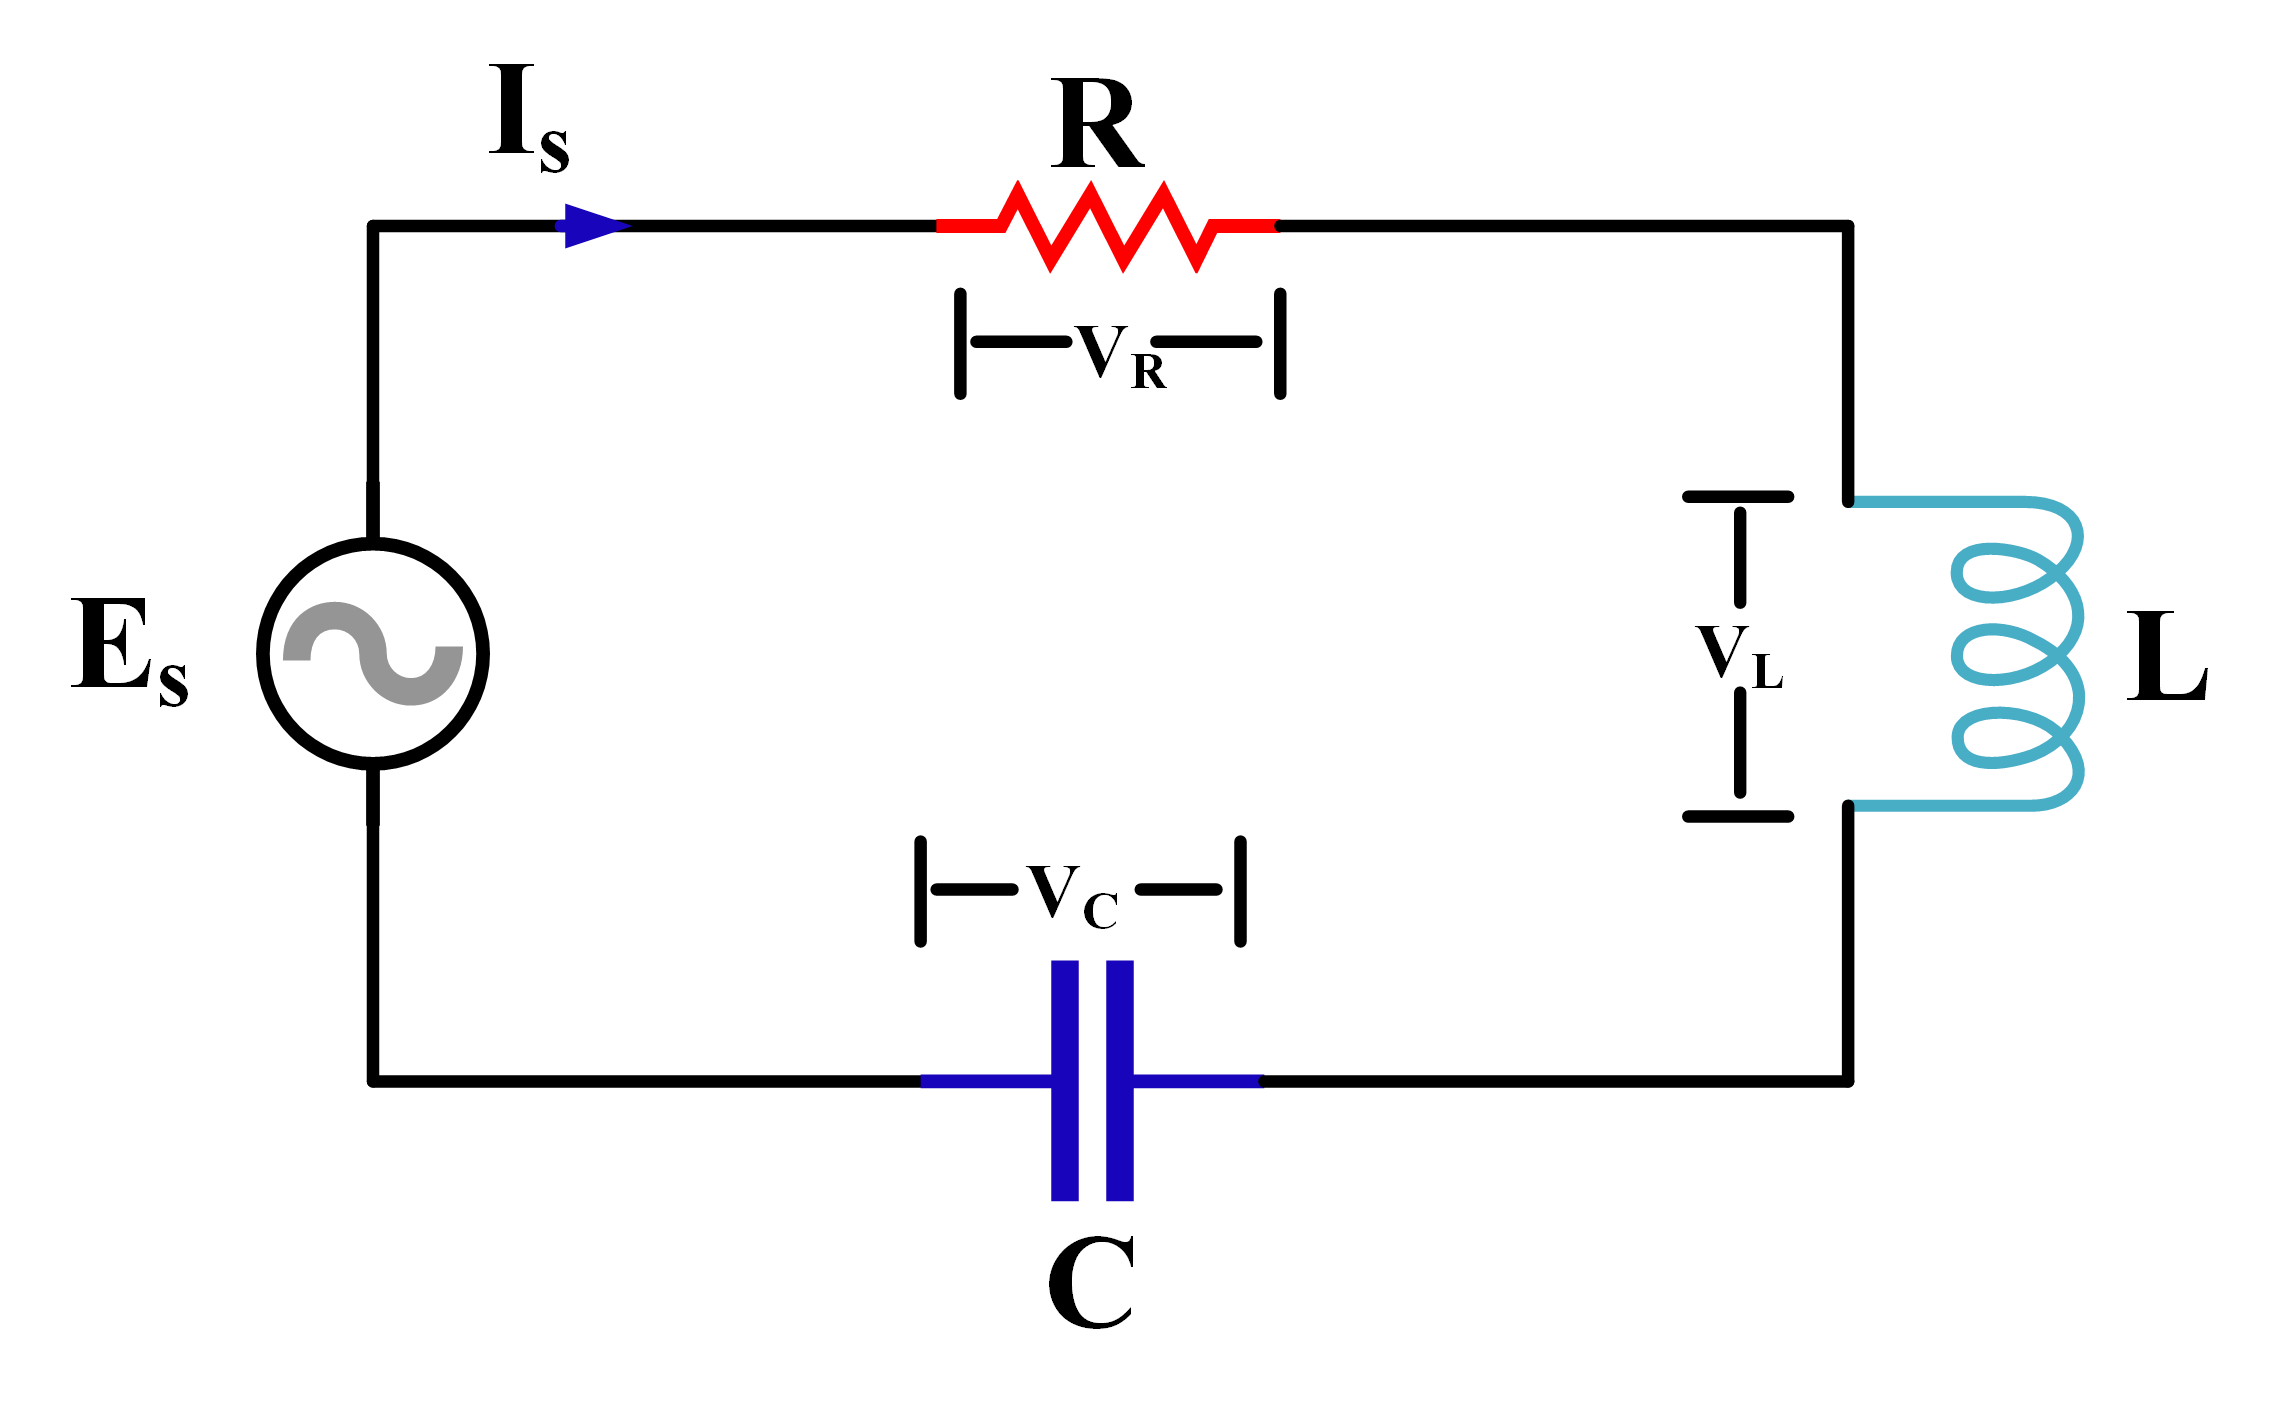

Vs = Vr + Vl + Vc

ic = CV'

Vs = I*R + I'*L + (1/C)*integral(I)

Vs = I' * R + I'' * L + (1/C)*I

clear all
close all
clc
syms I(t) t
dI(t) = diff(I)

$$dI(t) = \frac{\partial }{\partial t}\text{I}\left(t\right)$$

ddI(t) = diff(dI)

$$ddI(t) = \frac{\partial^{2}}{\partial t^{2}}\text{I}\left(t\right)$$


f = 60

f = 60

Vs = 120*sin(2*pi*f*t)

$$Vs = 120\,\sin\left(120\,\pi \,t\right)$$

R = 1e3;
L = 1e-3;
C = 1e-6;
ode = diff(Vs) == dI*R + ddI*L + (1/C)*I;
ics = [I(0) == 0, dI(0) == 0];
S = dsolve(ode, ics);
Gain = 1000

Gain = 1000

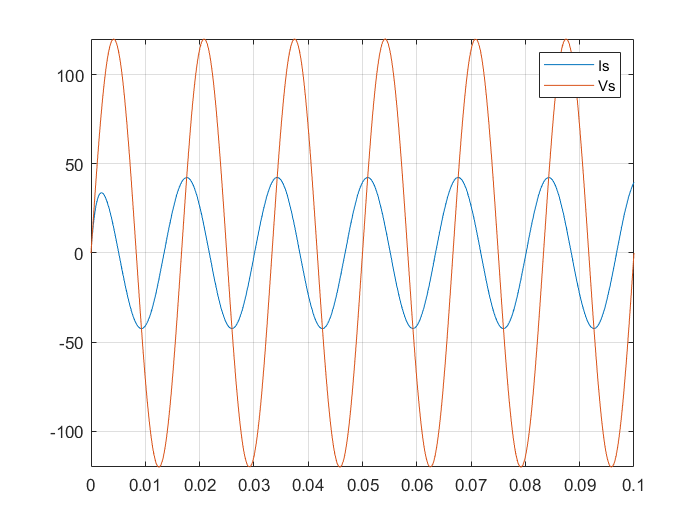

fplot(S*Gain)
xlim([0 0.1])
grid on
hold on
fplot(Vs)
legend("Is", "Vs")
hold off